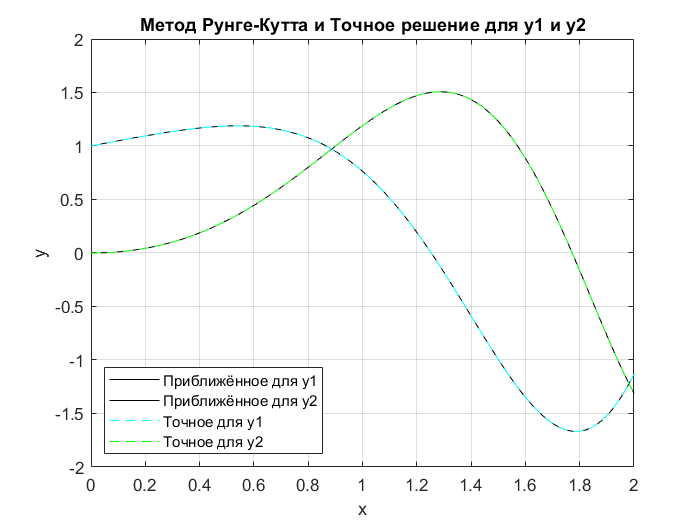

clear
clc
close all
u0_1 = 1;
u0_2 = 0;
h = 0.01;
a = 0;
b = 2;
n = (b-a)/h;
N = n+1;
x = a:h:b;

y1 = zeros(1, N);
y2 = zeros(1, N);

y1(1) = u0_1;
y2(1) = u0_2;

Y = [y1; y2];
Func = @(t, Y) [Y(1)/(2+2*t)-2*t*Y(2); Y(2)/(2+2*t)+2*t*Y(1)];

for i = 1:n
    K1 = Func(x(i), Y(:, i));
    K2 = Func(x(i)+h, Y(:, i)+h*K1);
    Y(:, i+1) = Y(:, i) + h*(0.5*K1+0.5*K2);
end

y1_ex = cos(x.*x).*sqrt(1+x);
y2_ex = sin(x.*x).*sqrt(1+x);


plot(x, Y(1, :), 'k',x, Y(2, :), 'k', x, y1_ex, '--c', x, y2_ex, '--g')
legend('Приближённое для y1', 'Приближённое для y2', 'Точное для y1', 'Точное для y2', 'Location','southwest')
grid on
title('Метод Рунге-Кутта и Точное решение для y1 и y2')
xlabel('x')
ylabel('y')